## **Plot solution space for GammaStar of rice using SEM ranges published in Hermida-Carrera et al (2016)**

Specify the temperature and the ideal gas constant:

Tp = 28.9310407291759;         % Average temperature in °C of measurements from gas exchange
R = 8.314/1000;                % Ideal gas constant in kJ K-1 mol-1

Generate a random normal distribution of potential $c$ and $\Delta H_a$ values using the mean $\pm \;\textrm{SEM}\;$for *O.sativa* in the paper by Hermida-Carrera et al (2016) :

% Constants
c_mean = 13.7;        % Mean for scaling constant c
c_SEM = 0.5;          % Standard error of mean for scaling constant c
dHa_mean = 24.6;      % Mean for activation energy dHa
dHa_SEM = 1.3;        % Standard error of mean for activation energy dHa
n = 100;              % Number of samples

% Generate random normal distribution of 100 values for c and dHa, scaled
% by their given SEM and shifted by their given means:
c_dist = c_mean + c_SEM * randn(n, 1);
dHa_dist = dHa_mean + dHa_SEM * randn(n, 1);

Calculate the number of possible combinations of Gamma Star at Tp using ranges of c and dHa: 

Gstar_combos = numel(c_dist) * numel(dHa_dist); 

Initialize the output vectors to store $c$, $\Delta H_a$, and their resulting Gamma Star values:

[c_values, dHa_values, Gstar_values] = deal(zeros(Gstar_combos,1)); 

Create an index to keep track of the position in the output vector :

i = 1; 

Create a nested loop to calculate Gamma Star for each pairwise combination of c and dHa:

for j = 1:numel(c_dist) 
    for k = 1:numel(dHa_dist) 
        % Calculate Gamma Star using the Arrhenius equation 
        Gstar = exp(c_dist(j) - dHa_dist(k) / (R * (Tp + 273.15))); 
        % Update the vectors with the values used to calculate Gstar 
        c_values(i) = c_dist(j); 
        dHa_values(i) = dHa_dist(k); 
        Gstar_values(i) = Gstar; 
        % Increment the index 
        i = i + 1; 
    end 
end

Visualise the generated distribution of Gamma Star values:

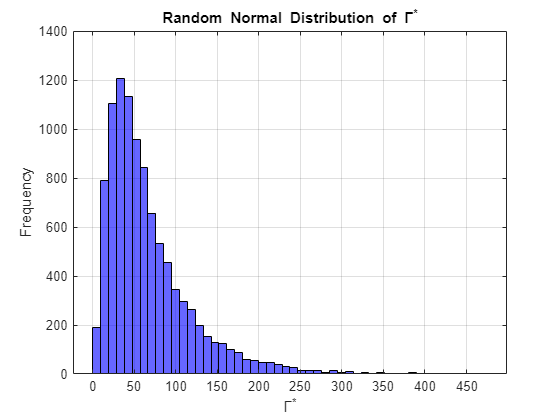

figure; 
histogram(Gstar_values, 50, 'FaceColor', 'b'); 
xlabel('\Gamma^*'); 
ylabel('Frequency'); 
title('Random Normal Distribution of \Gamma^*'); 
grid on;

Create a 3D scatter plot to examine values:

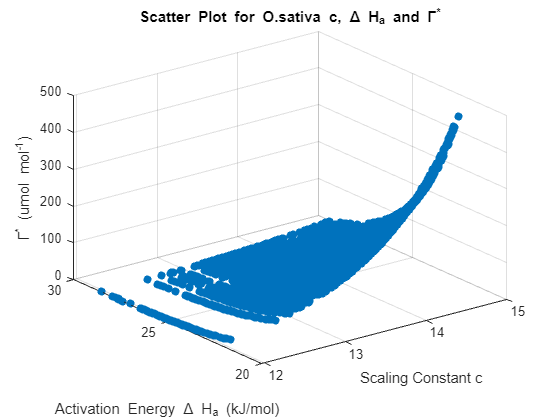

figure;
scatter3(c_values,dHa_values,Gstar_values,'filled');
xlabel('Scaling Constant c'); 
ylabel('Activation Energy \Delta H_a (kJ/mol)'); 
zlabel('\Gamma^* (umol mol^{-1})'); 
title('Scatter Plot for O.sativa c, \Delta H_a and \Gamma^*'); 

#### However! A more efficient calculation without loops can be achieved using meshgrid and a nicer-looking surface plot can be created with surf

Create a grid of all possible values of Gamma Star at Tp using ranges of c and dHa:

[c_grid, dHa_grid] = meshgrid(c_dist, dHa_dist);

Calculate Gamma Star for each combination using the Arrhenius equation:

Gstar_values_mesh = exp(c_grid - dHa_grid ./ (R * (Tp + 273.15)));

Plot the solution space using surf:

figure; 
surf(c_dist, dHa_dist, Gstar_values_mesh); 
xlabel('Scaling Constant c'); 
ylabel('Activation Energy \Delta H_a (kJ/mol)'); 
zlabel('\Gamma^* (umol mol^{-1})'); 
title('Solution Space for O.sativa \Gamma^*'); 
colorbar;

Export the figure:

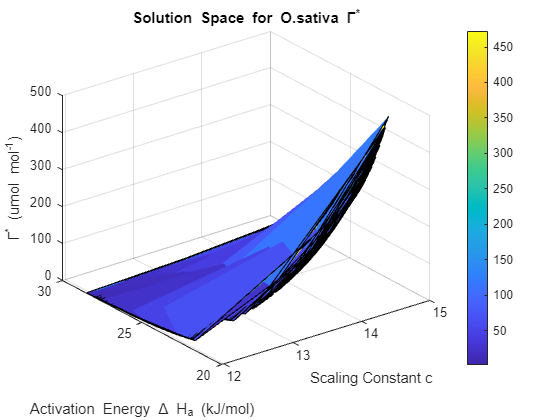

print(gcf,fullfile('Outputs/rice_params/graphs',"cdHa_vs_Gstar"),'-djpeg');

A t - test tests the null hypothesis that the population mean is `m` against the specified alternative hypothesis.

Conduct a one-tailed t-test to test the null hypothesis that $\Gamma^*$ from e-Photosynthesis is significantly different from the one used for the A/Cc fits.

The test statistic is:

#### 
$$t=\frac{\bar{x} -\mu }{s/\sqrt{n}}$$


where $\bar{x}$ is the sample mean, *μ* is the hypothesized population mean, *s* is the sample standard deviation, and *n* is the sample size. 

Under the null hypothesis, the test statistic has Student’s *t* distribution with *n* – 1 degrees of freedom.

Conduct a one-tailed t-test of the random G_star distribution against a hypothesised mean equal to the value used in the A/Cc fits:

%[h,p,ci,stats] = ttest(Gstar_values,0,'Tail','right')
[h,p,ci,stats] = ttest(Gstar_values,49.6558492521714,'Tail','right')

h = 1

p = 9.6772e-239

ci =    67.2079
       Inf


stats = struct with fields:
    tstat: 33.8916
       df: 9999
       sd: 54.4309


The outputs are the test statistic (t), degrees of freedom (df), p-value, and confidence interval (ci), which indicate whether the null hypothesis (mean $\Gamma^*$= 0) can be rejected.

The returned value of h=1 indicates that the test rejects the null hypothesis at the default significance level of 0.05 (5%), in favour of the alternative hypothesis that the data comes from a population with a mean greater than 49.65. The large t-value suggests there is a substantial difference between the sample mean and the hypothesised mean.

df = number of samples - 1 (Gstar_combos - 1 = 9999).

sd is standard deviation - spread of Gstar values in distribution. 

p<<<0 means the null can be confidently rejected.

The lower and upper bounds of the confidence intervals are given, meaning $\Gamma^*$is confidently higher than the lower bound at the given confidence level of 95%.